function outFrame=blacken_background(thisFrame)

Paint the background of the cartoon black and return the image

Steps in the process are 

- - Perform edge detection to isolate regions 

- - Find the largest regions by area 

- - Set the colour in significant regions to their median (for clustering only) 

- - Perform image segmentation by clustering on the median colours 

- - Determine if the largest non-white area is defined by cluster or colour and set that to the background 

- - Search other areas for background characteristics 

- - Apply the background as an inverted mask to the input image and return

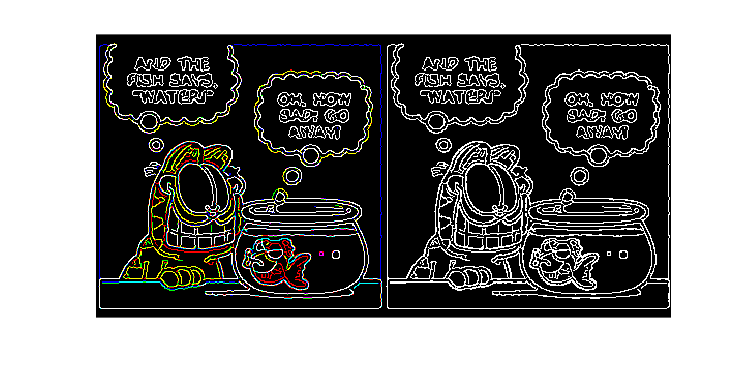

% function outFrame=blacken_background(thisFrame)
g=1;
[frameMask, frameEdges]=mask_frames(rotatedImages{g});
s=2;

% Find the column range for this frame
frameRange=(frameEdges(s)+1):frameEdges(s+1);
thisFrame=rotatedImages{g}(:,frameRange,:);

% Find width and height of frame
[imHeight,imWidth,~]=size(thisFrame);

% Perform edge detection on all colours
imEdges3d=zeros(size(thisFrame));
for c=1:3
    imEdges3d(:,:,c)=edge(thisFrame(:,:,c),'Canny');
end
imEdges=any(imEdges3d,3);
image_show_resize(imtile({imEdges3d,imEdges}));

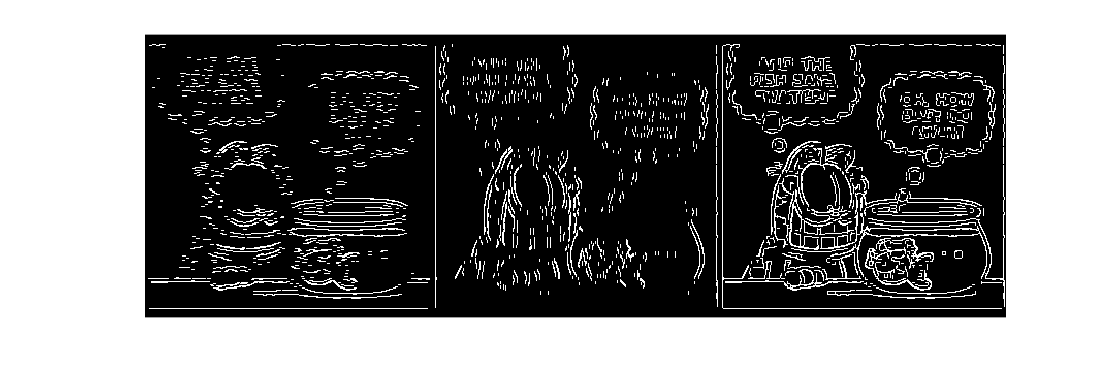


% Remove components from edges that aren't significant horizontal lines
imEdgesH=imopen(imEdges,strel('line',3,0));
imEdgesV=imopen(imEdges,strel('line',3,90));

% Find coordinates of edge pixels
imEdgesSteps=imtile({imEdgesH,imEdgesV,imEdgesH|imEdgesV},'GridSize',[1 NaN]);
image_show_resize(imEdgesSteps);

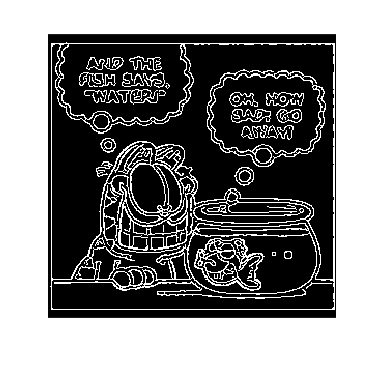


[yy, xx] = find(imEdgesH|imEdgesV);
[x1, x2]=bounds(xx);
[y1, y2]=bounds(yy);

% Burn new lines into the images to add a hard border around the frame
imEdges(y1,x1:x2)=1;imEdges(y2,x1:x2)=1;
imEdges(y1:y2,x1)=1;imEdges(y1:y2,x2)=1;
image_show_resize(imEdges);

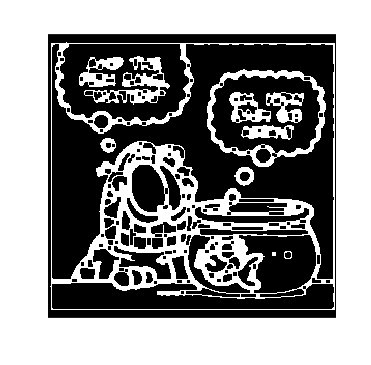

% Fill in the edges
se=strel('square',3);
imEdges=imclose(imEdges,se);
image_show_resize(imEdges);

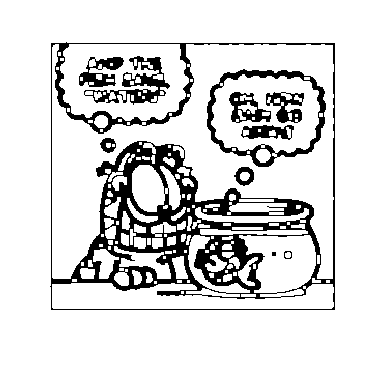


% Complement edges to get regions
imRegions=imcomplement(imEdges);
image_show_resize(imRegions);

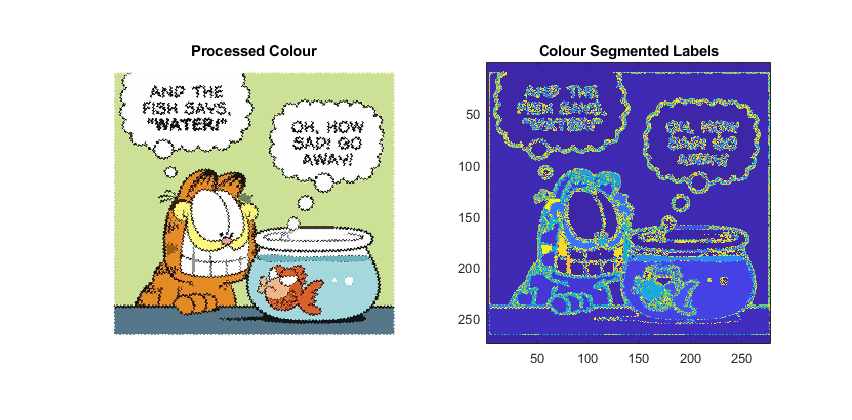


% Find the largest regions
cc=bwconncomp(imRegions,4);
regionStats=regionprops(cc,'Area','PixelIdxList');
regionArea=[regionStats.Area];
[regionAreaSort, maxRegionIdx]=sort(regionArea,'descend');
csum=cumsum(regionAreaSort)/sum(regionArea);

% Ignore the smallest regions
maxChangeRegions=find(csum>0.95,1);
if length(maxRegionIdx) > maxChangeRegions
    maxRegionIdx((maxChangeRegions+1):end)=[];
end

% Create a pixel vector for processing
thesePixels1=reshape(thisFrame,[],3);

% Check that the largest area isn't nearly white, as these can be border
% areas or speech bubbles.
bgndSearch=true;
while (bgndSearch && (length(maxRegionIdx)>1))
    % Use the median colour of a region to determine if it is mostly white
    levelCheck=median(thesePixels1(regionStats(maxRegionIdx(1)).PixelIdxList,:),1);
    
    % If this region is white then remove it from the index list
    if min(levelCheck)>= 240
        maxRegionIdx(1)=[];
    else
        bgndSearch=false;
    end
end

% Set all pixels colours in a region to a single colour
thesePixels2=reshape(thisFrame,[],3);
for r=1:length(maxRegionIdx)
    rPixels=regionStats(maxRegionIdx(r)).PixelIdxList;
    medFrame=median(thesePixels2(rPixels,:),1);
    for c=1:3
        thesePixels2(rPixels,c)=medFrame(c);
    end
end
thisFrame2=reshape(thesePixels2,size(thisFrame,1),[],3);

% Perform k-means clustering with k samples
[segLabels, segColours] = imsegkmeans(thisFrame2,56);
hfSeg=figure;subplot(1,2,1),imshow(thisFrame2), title('Processed Colour');
subplot(1,2,2),imagesc(segLabels),axis equal,axis tight;
title('Colour Segmented Labels')
hfSeg.Position(3)=2*imWidth/imHeight*hfSeg.Position(4);

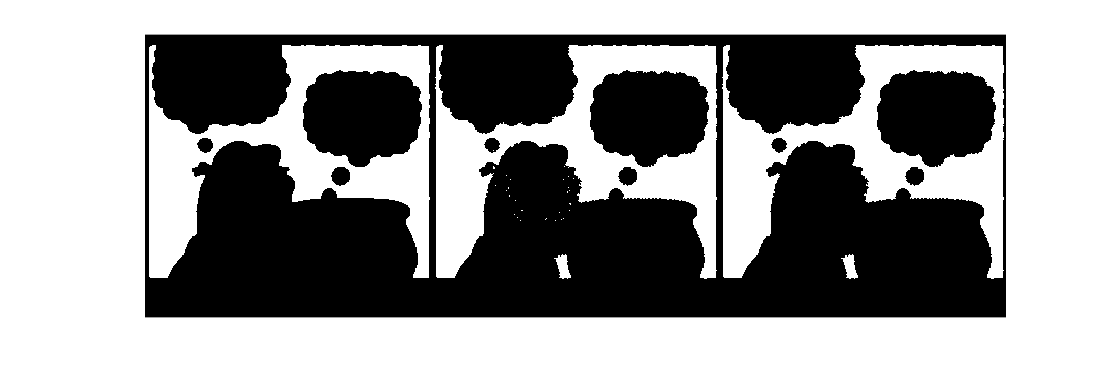


% Count the number of pixels in a label
[segLabelsCount, segCats]=histcounts(categorical(segLabels));

% Sort the label pixel count
[~,segIdx]=sort(segLabelsCount,'descend');

% Check that the largest area isn't nearly white, as these can be border
% areas or speech bubbles.
bgndSearch=true;
while (bgndSearch && (length(segIdx)>1))
    levelCheck = segColours(str2double(segCats{segIdx(1)}),:);
    if min(levelCheck)>= 240
        % If this region is white then remove it from the index list
        segIdx(1)=[];
    else
        % Largest area of non-white colour is found
        bgndSearch=false;
    end
end
largestColourArea=segLabelsCount(segIdx(1));

% Initialise background pixel index
bgAreaIdx=zeros(size(thesePixels1,1),1);

% Check if the number of pixels in an area or a colour is larger, biased to
% an area.
if regionStats(maxRegionIdx(1)).Area > 0.75*largestColourArea

    % Area is larger, tag the largest region as background
    bgAreaIdx(regionStats(maxRegionIdx(1)).PixelIdxList)=1;

    % Find label(s) appearing in the background
    bgndLabels=segLabels(regionStats(maxRegionIdx(1)).PixelIdxList);
    bgndCat=categorical(bgndLabels);

    % Get probabilties of a label in the background
    [bgLabelCount,bgLabelCat]=histcounts(bgndCat,'Normalization','probability');

    % Ignore labels with a probabilty of < 0.05
    bgLabelCat(bgLabelCount<0.05)=[];
    bgLabelCount(bgLabelCount<0.05)=[];

    % Set all labelled areas in the same group as the background to background
    bgndIdx2=ismember(segLabels,str2num(char(bgLabelCat)));  %#ok<*ST2NM>

    % Reshape the colour indicies to the shape of the frame
    bkgndByColour=reshape(bgndIdx2,imHeight,imWidth);
else
    % Colour region is larger, tag the most common colour as the background
    bgLabel = str2double(segCats{segIdx(1)});

    % Find the background pixels in the image
    bkgndByColour=(segLabels==bgLabel);

    % Add the region to the background list if it is at least 20% of the
    % largest area by colour, and has at least 50% of its pixels in the
    % background colour
    for r=maxRegionIdx
        if regionStats(r).Area > 0.2*largestColourArea
            if sum(bkgndByColour(regionStats(r).PixelIdxList)) > 0.5
               bgAreaIdx(regionStats(r).PixelIdxList)=1;
            end
        end
    end
end

bkgndByArea=reshape(bgAreaIdx,imHeight,imWidth);

% Only add pixels by colour to the background if there are a sufficient
% number of pixels in a region.
bkgndByColour2=zeros(size(bkgndByColour));
ccbg=bwconncomp(bkgndByColour,4);
for r=1:ccbg.NumObjects
    if length(ccbg.PixelIdxList{r})>6
        bkgndByColour2(ccbg.PixelIdxList{r})=1;
    end
end

bkgndImage=imtile({bkgndByArea,bkgndByColour,bkgndByColour2},'GridSize',[1 NaN]);
image_show_resize(bkgndImage);

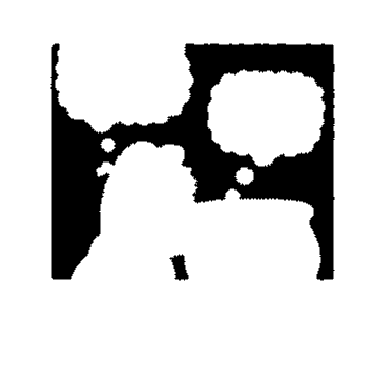


% Create a foreground mask region for preserving the original image
foreGndMask1=~(bkgndByArea|bkgndByColour2);

% Structuring Element
se=strel('disk',1);%strel('square',3);

% Erode the foreground mask
foreGndMask2=imerode(foreGndMask1,se);

% Take the average of the foreground masks
foreGndMask1=0.5*(foreGndMask1+foreGndMask2);
image_show_resize(foreGndMask1);

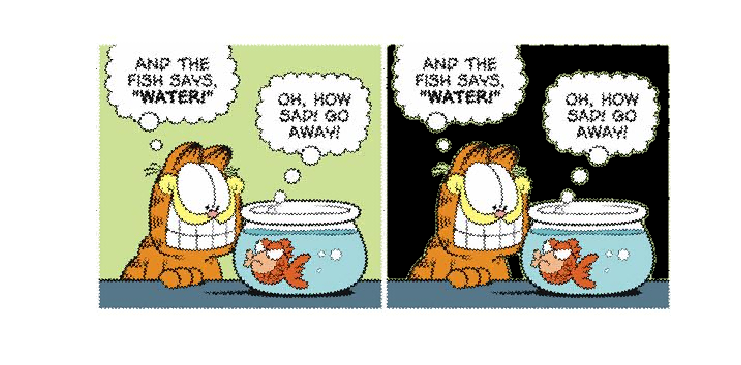


% Replicate the mask for each colour
foreGndMask1=repmat(foreGndMask1,1,1,3);

% Apply the mask to the original frame and return
outFrame=cast(single(thisFrame).*foreGndMask1,'like',thisFrame);
image_show_resize(imtile({thisFrame,outFrame}));